# **Calculate M and Theta (2 equations, 2 solutions)**

On the other script ('Calculate_M_Theta_UniqueSolution_Sym.mlx') we used the Symbolic Toolbox to solve the equations symbolic, but here we use 'lsqnonlin'  to be consistent with the 'Calculate_M_Theta_ApproximateSolution.mlx' and also in order not to use 2 Toolboxes.

**Last Update:** 04/Mar/2020

## **Addpaths**

clear all
clc
close all
addpath(genpath('C:\Users\Rita\Documents\MATLAB\spm8'))
path ='C:\Users\Rita\Desktop\CHUV_Tests';
addpath(genpath(path))
cd(path)

## Comparison lsqnonlin and vpasolve

#### !! Comment this section if no 'Symbolic ToolBox' is available !!

% Initiate
alpha  = 0.1;
beta   = 0.7;
g      = 0.7;
v      = 10;
p      = 5.5;

% Compute solution with lsqnonlin
x0      = [0.3;0.1]; % First guess on M and theta
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
res     = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option

% Compute solution with symbolic solver vpasolve
syms M theta
[~, ~,v_sym_eqn_GammaLevel] = make_sym_equations_v(M,theta,v,alpha,beta,1);
[~, ~,g_sym_eqn_GammaLevel] = make_sym_equations_g(M,theta,g,alpha,beta,1);
[s1, s2]    = vpasolve([g_sym_eqn_GammaLevel v_sym_eqn_GammaLevel],[M theta],[0 1; 0 1]);
sprintf('fsolver - Mode is: %.003f and Theta is: %.003f',res(1),res(2))

ans = 'fsolver - Mode is: 0.347 and Theta is: 0.271'

sprintf('vpasolve - Mode is: %.003f and Theta is: %.003f',s1, s2)

ans = 'vpasolve - Mode is: 0.347 and Theta is: 0.271'

**Comments:**

The solvers give the same solution if the 'FunctionTolerance' is 10^-7 or less. If it is bigger than than (10^-6) the solution given by the solver is just an approximation of the real solution. We can only use the lsqnonlin from now one.

## G as a function of r

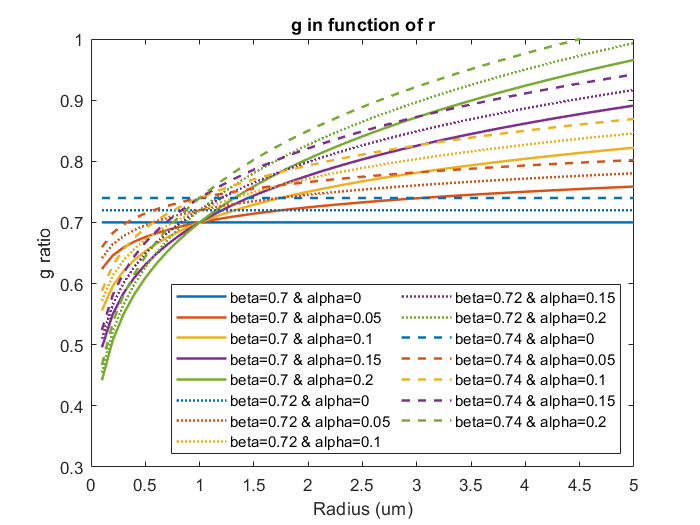

% Initiate
r       = 0.1:0.1:5;
lgd     = cell(15,1);
k       = 1;
ls = {'-','-','-','-','-',':',':',':',':',':','--','--','--','--','--'};
Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880;...
    0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; ...
    0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880];

% Loop for betas and alphas
figure()
for beta=0.7:0.02:0.74
    for alpha=0:0.05:0.2
        g       = beta.*r.^alpha;
        lgd{k}  = strcat('beta=',num2str(beta),' & alpha=', num2str(alpha));
        plot(r,g,'LineStyle',ls{k},'LineWidth',1.5,'color',Color_list(k,:))
        hold on
        k       = k+1;
    end
end
xlabel('Radius (um)')
ylabel('g ratio')
ylim([0.3 1])
title('g in function of r')
legend(lgd,'location','southeast','NumColumns',2)
saveas(gcf,fullfile(path,'ImagesResults','Alpha_Beta_Sensibility.png'))

## EQUATION 1 - Solve (assume theta)

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02;
g       = 0.7;
%syms M
theta = 0.25;

% Set options for solver
x0      = 0.4;
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');

% Solve different levels
res_Easy     = lsqnonlin(@(M) g_eqn_EasyLevel(M,theta,g,alpha,beta,A),x0,0,0.8,options); % other option
res_Hard     = lsqnonlin(@(M) g_eqn_HardLevel(M,theta,g,alpha,beta),x0,0,0.8,options); % other option
res_Gamma    = lsqnonlin(@(M) g_eqn_GammaLevel(M,theta,g,alpha,beta),x0,0,0.8,options); % other option

sprintf('Easy level: %.003f \n Hard level: %.003f \n Gamma level: %.003f ',res_Easy,res_Hard,res_Gamma)

ans =     'Easy level: 0.494 
      Hard level: 0.407 
      Gamma level: 0.398 '


## EQUATION 1 - Solve (assume mode)

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02;
g       = 0.70;
M       = 0.4;

% Set options for solver
x0      = 0.2;
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');

% Solve different levels
res_Easy     = lsqnonlin(@(theta) g_eqn_EasyLevel(M,theta,g,alpha,beta,A),x0,0.1,0.8,options); % other option
res_Hard     = lsqnonlin(@(theta) g_eqn_HardLevel(M,theta,g,alpha,beta),x0,0.1,0.8,options); % other option
res_Gamma    = lsqnonlin(@(theta) g_eqn_GammaLevel(M,theta,g,alpha,beta),x0,0.1,0.8,options); % other option

sprintf('Easy level: %.003f \n Hard level: %.003f \n Gamma level: %.003f ',res_Easy,res_Hard,res_Gamma)

ans =     'Easy level: 0.349 
      Hard level: 0.253 
      Gamma level: 0.249 '


## EQUATION 1 - Plot in function of theta and M 

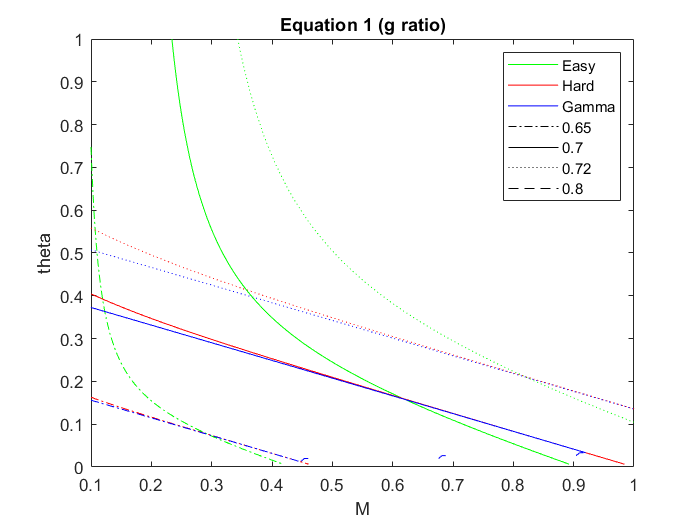

% Initiate
alpha = 0.1;
beta = 0.7;
A  = 1.02;
G = [0.65,0.72,0.8,0.70];
ls = {'-.',':','--','-'};

% Loop for different g ratios
figure()
for i=1:length(G)
    g=G(i);
    
    % Plot
    warning('off')
    p1 = fimplicit(@(M,theta) g_eqn_EasyLevel(M,theta,g,alpha,beta,A),'Color','g','LineStyle',ls{i});
    hold on
    warning('off')
    p2 = fimplicit(@(M,theta) g_eqn_HardLevel(M,theta,g,alpha,beta),'Color','r','LineStyle',ls{i});
    hold on
    warning('off')
    p3 = fimplicit(@(M,theta) g_eqn_GammaLevel(M,theta,g,alpha,beta),'Color','b','LineStyle',ls{i});
end

% Plot stuff just to make legend
hold on
st1 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-.');
hold on
st2 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-');
hold on
st3 = plot([-2,-1],[-2,-1],'Color','k','LineStyle',':');
hold on
st4 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','--');

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,p3,st1,st2,st3,st4],{'Easy','Hard','Gamma','0.65','0.7','0.72','0.8'})
title('Equation 1 (g ratio)')
saveas(gcf,fullfile(path,'ImagesResults','Equation1_Levels.png'))

#### Comments:

The easy approximation doesn't behave as the Hard approximation or the Gamma. 

For bigger Thetas the function "explodes". As we can see below, the lower the mode, the bigger the ratio has to be in order to represent the gamma ratio as accurate as possible.

Fixating the ratio to just one value that is constant for each mode and each theta creates a bias in the equation that is bigger for lower modes.

## Equation 1 - Sensibility Evaluation 

### 1. Easy Ratio btw 2 gammas:

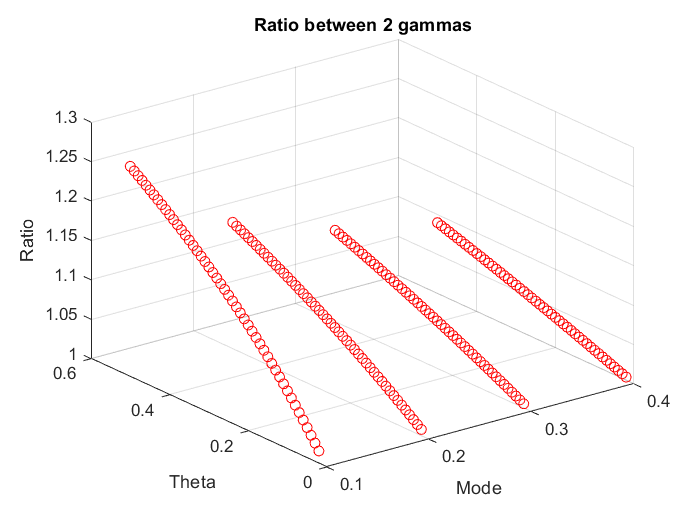

figure()
for mode=0.1:0.1:0.4
    for theta=0.02:0.01:0.5
        LL      = (mode/theta)^(2*alpha); % lower limit approximation
        UL      = (mode/theta + 1)^(2*alpha); % Upper limit approximation
        TV      = gamma(mode/theta+1)/gamma(mode/theta+1-2*alpha); % true ratio between gammas
        
        ratio   = TV/LL;
        
        scatter3(mode,theta,ratio,'r')
        hold on
    end
end
xlabel('Mode')
ylabel('Theta')
zlabel('Ratio')
title('Ratio between 2 gammas')
saveas(gcf,fullfile(path,'ImagesResults','Equation1_Ratio.png'))

### 2. Bias in Gamma true function:

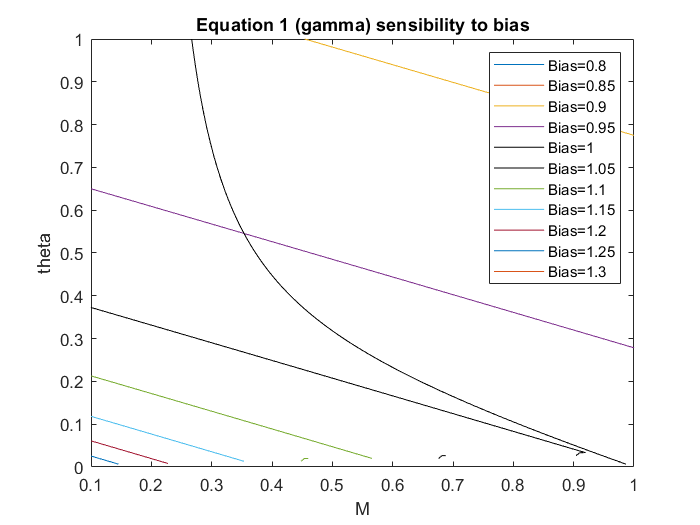

% Initiate
alpha       = 0.1;
beta        = 0.7;
g           = 0.7;
lgd         = cell(11,1);
k           = 1;

% Loop for different bias
figure()
for i=0.8:0.05:1.3
    Abias = i;
    
    % Plot
    if Abias==1
        warning('off')
        fimplicit(@(M,theta) g_eqn_GammaLevel(M,theta,g,alpha,beta),'Color','k');
        hold on
        warning('off')
        fimplicit(@(M,theta) g_eqn_EasyLevel(M,theta,g,alpha,beta,1),'Color','k');
    else
        warning('off')
        fimplicit(@(M,theta) g_eqn_GammaLevel(M,theta,g/Abias,alpha,beta));
        hold on
    end
    
    % Legend
    lgd{k}  = strcat('Bias=',num2str(i));
    k       = k+1;
end

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend(lgd)
title('Equation 1 (gamma) sensibility to bias')
saveas(gcf,fullfile(path,'ImagesResults','Equation1_Bias.png'))

**Comments**:

As we can see, the lower the bias, aka, if we underestimate the ratio (that is what we are doing for lower modes if we assume a constant ratio of 1.02 for example) the bias is bigger, therefore the shift of the equation is quite big, leading to a big bias in the solution.

eg. For a mode of 0.2 (and a theta of ~0.1,), the ratio between the true value and the lower limit that we are using as an approximation is ~1.04. This means that if I don't use an accurate factor to account for the bias in the gamma ratios and use just the lower limit, we will be underestimating the solution by 1/1.04=0.96 which is an accordance with the last graph. 

The same is not true for equation 2, as we can see above.

## Equation 2 - Sensibility Evaluation 

### 1. Easy Ratio btw 2 gammas: 

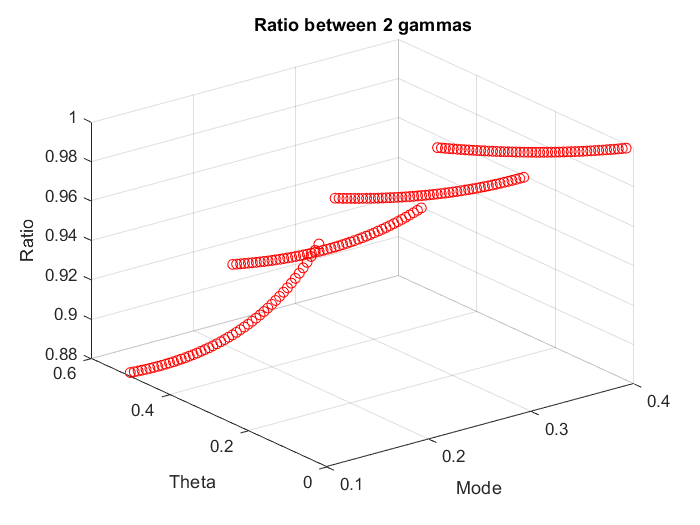

figure()
for mode=0.1:0.1:0.4
    for theta=0.02:0.01:0.5
        UL      = (mode/theta)^(-alpha); % upper limit approximation
        LL      = (mode/theta + 1)^(-alpha); % lower limit approximation
        TV      = gamma(mode/theta+1-alpha)/gamma(mode/theta+1); % true ratio between gammas
        
        ratio   = TV/UL;
        
        scatter3(mode,theta,ratio,'r')
        hold on
    end
end
xlabel('Mode')
ylabel('Theta')
zlabel('Ratio')
title('Ratio between 2 gammas')
saveas(gcf,fullfile(path,'ImagesResults','Equation2_Ratio.png'))

### 2. Bias in Gamma true function:

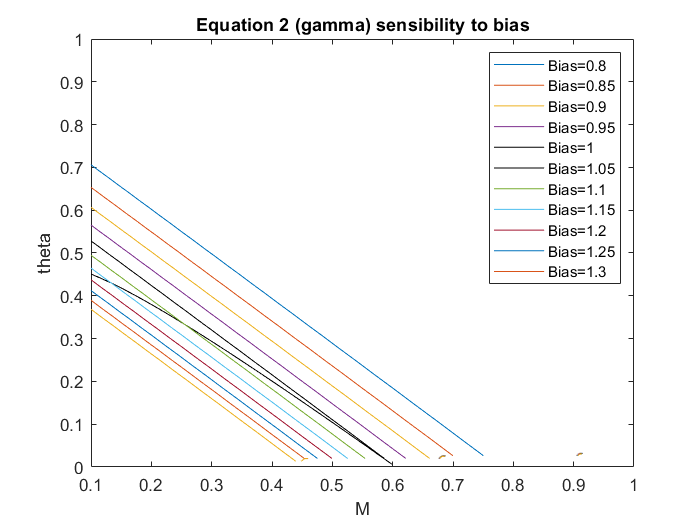

% Initiate
alpha       = 0.1;
beta        = 0.7;
v           = 10;
p           = 5.5;
lgd         = cell(11,1);
k           = 1;

% Loop for different bias
figure()
for i=0.8:0.05:1.3
    Cbias = i;
    
    % Plot
    if Cbias==1
        warning('off')
        fimplicit(@(M,theta) v_eqn_GammaLevel(M,theta,v,alpha,beta,p),'Color','k');
        hold on
        warning('off')
        fimplicit(@(M,theta) v_eqn_EasyLevel(M,theta,v,alpha,beta,1),'Color','k');
        hold on
    else
        warning('off')
        fimplicit(@(M,theta) v_eqn_GammaLevel(M,theta,v/Cbias,alpha,beta,p));
        hold on
    end
    
    % Legend
    lgd{k}  = strcat('Bias=',num2str(i));
    k       = k+1;
end

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend(lgd)
title('Equation 2 (gamma) sensibility to bias')
saveas(gcf,fullfile(path,'ImagesResults','Equation2_Bias.png'))

**Comments**:

Here the bias don't implicate such a big shift in the equation, so the same bias as before don't lead to such big differences if we use

approximations. 

eg. For a mode of 0.2 (and a theta of ~0.21,), the ratio between the true value and the lower limit that we are using as an approximation is 

~0.96. This means that if I don't use an accurate factor to account for the bias in the gamma ratios and use just the lower limit, we will be 

underestimating the solution by 1/0.96=1.04 which is an accordance with the last graph. 

The same bias in equation 2 doesn't lead to bigger differences in the funciton because this function is not so susceptible to bias, as opposite

to the g-ratio function (equation 1).

## EQUATION 2 - Solve (assume M)

% Initiate
alpha   = 0.1;
beta    = 0.7;
C       = 0.98;
p       = 5.5;
v       = 10;
M       = 0.3;

% Set options for solver
x0      = 0.1;
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');

% Solve different levels
res_Easy     = lsqnonlin(@(theta) v_eqn_EasyLevel(M,theta,v,alpha,beta,C),x0,[],[],options); % other option
res_Hard     = lsqnonlin(@(theta) v_eqn_HardLevel(M,theta,v,alpha,beta),x0,[],[],options); % other option
res_Gamma    = lsqnonlin(@(theta) v_eqn_GammaLevel(M,theta,v,alpha,beta,p),x0,[],[],options); % other option

sprintf('Easy level: %.003f \n Hard level: %.003f \n Gamma level: %.003f ',res_Easy,res_Hard,res_Gamma)

ans =     'Easy level: 0.306 
      Hard level: 0.318 
      Gamma level: 0.320 '


## EQUATION 2 - Plot in function of theta and M 

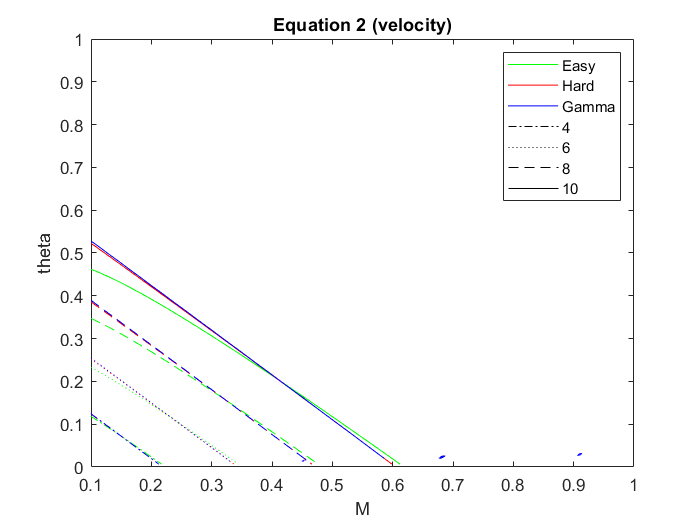

% Initiate
alpha   = 0.1;
beta    = 0.7;
C       = 0.98;
p       = 5.5;
V = [4, 6, 8, 10];
ls = {'-.',':','--','-'};

% Loop for different velocities
figure()
for i=1:length(V)
    v=V(i);
    
    % Plot
    warning('off')
    p1 = fimplicit(@(M,theta) v_eqn_EasyLevel(M,theta,v,alpha,beta,C),'Color','g','LineStyle',ls{i});
    hold on
    p2 = fimplicit(@(M,theta) v_eqn_HardLevel(M,theta,v,alpha,beta),'Color','r','LineStyle',ls{i});
    hold on
    p3 = fimplicit(@(M,theta) v_eqn_GammaLevel(M,theta,v,alpha,beta,p),'Color','b','LineStyle',ls{i});
end

% Plot stuff just to make legend
hold on
st1 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-.');
hold on
st2 = plot([-2,-1],[-2,-1],'Color','k','LineStyle',':');
hold on
st3 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','--');
hold on
st4 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-');

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,p3,st1,st2,st3,st4],{'Easy','Hard','Gamma','4','6','8','10'})
title('Equation 2 (velocity)')
saveas(gcf,fullfile(path,'ImagesResults','Equation2_Levels.png'))

**Comments:**

Here the problem that appeared with equation 1, of the easy approximation don't follow the ground truth doesn't happen, as we already saw before.

## EQUATION 1 & 2 - Plot in function of M and theta and fixed g

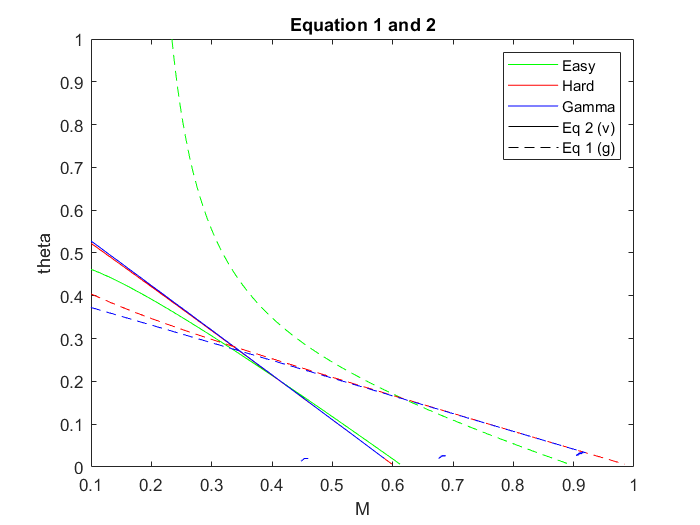

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02;
C       = 0.98;
p       = 5.5;
g       = 0.7;
v       = 10;

figure()

% Plot
warning('off')
p1 = fimplicit(@(M,theta) v_eqn_EasyLevel(M,theta,v,alpha,beta,C),'Color','g','LineStyle','-');
hold on
p2 = fimplicit(@(M,theta) v_eqn_HardLevel(M,theta,v,alpha,beta),'Color','r','LineStyle','-');
hold on
p3 = fimplicit(@(M,theta) v_eqn_GammaLevel(M,theta,v,alpha,beta,p),'Color','b','LineStyle','-');
hold on
p4 = fimplicit(@(M,theta) g_eqn_EasyLevel(M,theta,g,alpha,beta,A),'Color','g','LineStyle','--');
hold on
fimplicit(@(M,theta) g_eqn_HardLevel(M,theta,g,alpha,beta),'Color','r','LineStyle','--');
hold on
fimplicit(@(M,theta) g_eqn_GammaLevel(M,theta,g,alpha,beta),'Color','b','LineStyle','--');
hold on
st1 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-');
hold on
st2 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','--');

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,p3,st1,st2],{'Easy','Hard','Gamma','Eq 2 (v)','Eq 1 (g)'})
title('Equation 1 and 2')
saveas(gcf,fullfile(path,'ImagesResults','Equation1_2_Levels.png'))

**Comments:**

We want to find the intersection between these 2 equations. They depend a lot on the velocity and g-ratios given.

##  EQUATION 1 & 2 - Plot in function of M and theta, several g and v

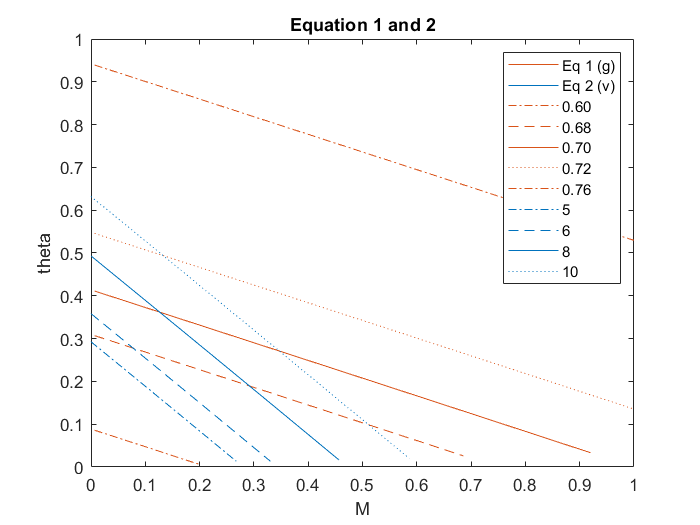

% Initiate
alpha   = 0.1;
beta    = 0.70;
A       = 1.02;
C       = 0.98;
p       = 5.5;
G = [0.6, 0.68, 0.70, 0.72, 0.76];
V = [5, 6, 8, 10];
ls = {'-.','--','-',':','-.'};

% Loop for different g ratios
figure()
warning('off')
for i=1:length(G)
    g=G(i);
    
    % Plot
    fimplicit(@(M,theta) g_eqn_GammaLevel(M,theta,g,alpha,beta),'Color',[0.8500, 0.3250, 0.0980],'LineStyle',ls{i});
    hold on
end


for i=1:length(V)
    v=V(i);
    
    % Plot
    fimplicit(@(M,theta) v_eqn_GammaLevel(M,theta,v,alpha,beta,p),'Color',[0, 0.4470, 0.7410],'LineStyle',ls{i});
    hold on
end

% Plot stuff just to make legend
hold on
p1 = plot([-2,-1],[-2,-1],'Color',[0.8500, 0.3250, 0.0980],'LineStyle','-');
hold on
p2 = plot([-2,-1],[-2,-1],'Color',[0, 0.4470, 0.7410],'LineStyle','-');
hold on
st1 = plot([-2,-1],[-2,-1],'LineStyle','-.','Color',[0.8500, 0.3250, 0.0980]);
hold on
st2 = plot([-2,-1],[-2,-1],'LineStyle','--','Color',[0.8500, 0.3250, 0.0980]);
hold on
st3 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',[0.8500, 0.3250, 0.0980]);
hold on
st4 = plot([-2,-1],[-2,-1],'LineStyle',':','Color',[0.8500, 0.3250, 0.0980]);
hold on
st5 = plot([-2,-1],[-2,-1],'LineStyle','-.','Color',[0.8500, 0.3250, 0.0980]);
hold on
st6 = plot([-2,-1],[-2,-1],'LineStyle','-.','Color',[0, 0.4470, 0.7410]);
hold on
st7 = plot([-2,-1],[-2,-1],'LineStyle','--','Color',[0, 0.4470, 0.7410]);
hold on
st8 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',[0, 0.4470, 0.7410]);
hold on
st9 = plot([-2,-1],[-2,-1],'LineStyle',':','Color',[0, 0.4470, 0.7410]);
hold on

xlim([0,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,st1,st2,st3,st4,st5,st6,st7,st8,st9],{'Eq 1 (g)','Eq 2 (v)','0.60', '0.68', '0.70', '0.72', '0.76','5','6','8','10'})
title('Equation 1 and 2')
saveas(gcf,fullfile(path,'ImagesResults','Equation1_2_GV.png'))

**Comments**:

Tiny differences in the g-ratio (0.02 for example) can lead to big differences in the Mode and Theta pairs, respectively 0.15 and and 0.11 approximatly. 

This will happen in real life, since we would have some noise in the g-ratios. See next section.

## EQUATION 1 & 2 - Sensibility to noise

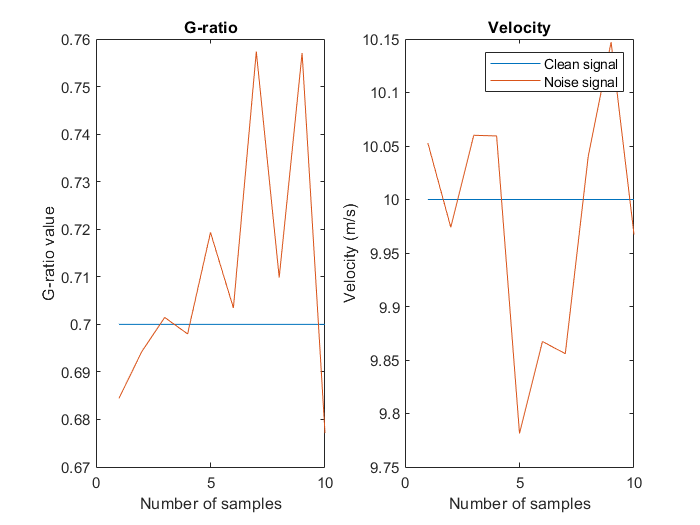

% Initiate
alpha   = 0.1;
beta    = 0.7;
p       = 5.5;
G_raw   = 0.7*ones(10,1);
V_raw   = 10*ones(10,1);
G       = awgn(G_raw,30);
V       = awgn(V_raw,20);

figure()
subplot(1,2,1)
plot(1:10,G_raw)
hold on
plot(1:10,G)
title('G-ratio')
xlabel('Number of samples')
ylabel('G-ratio value')
subplot(1,2,2)
plot(1:10,V_raw)
hold on
plot(1:10,V)
title('Velocity')
xlabel('Number of samples')
ylabel('Velocity (m/s)')
legend('Clean signal','Noise signal')


S1 = [];
S2 = [];

for i=1:length(G)
    g   = G(i);
    v   = V(i);
    
    % Set options for solver
    x0      = [0.3; 0.2];
    options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
    
    % Solve
    res    = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[],[],options); % other option
    S1          = [S1; res(1)];
    S2          = [S2; res(2)];
end

meanMode    = mean(S1);
meanTheta   = mean(S2);
stdMode     = std(S1);
stdTheta    = std(S2);

sprintf('Mean mode is: %.02f +/- %.02f',meanMode,stdMode)

ans = 'Mean mode is: 0.19 +/- 0.35'

sprintf('Mean Theta is: %.02f +/- %.02f',meanTheta,stdTheta)

ans = 'Mean Theta is: 0.43 +/- 0.37'

**Comments:**

If we increase the noise level, the mean and std deviations of mode and theta can get quite high. This method is not so efficient as trying to solve all with all the g's at once, using a least square method. To handle this go to the other script.

## EQUATION 1 & 2 - Sensibility to Alpha and Beta

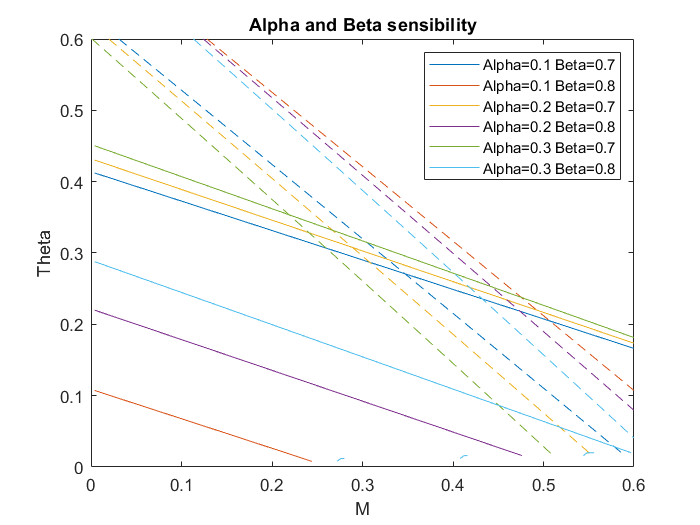

% Initiate
Alpha   = [0.1, 0.2, 0.3];
Beta    = [0.7, 0.8];
p       = 5.5;
g = 0.7;
v = 10;
Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880];
lgn = cell(6,1);
k       = 1;

% Loop for different alphas e betas
figure()
for i=1:length(Alpha)
    alpha = Alpha(i);
    for j=1:length(Beta)
        beta = Beta(j);
        
        % Plot
        warning('off')
        fimplicit(@(M,theta) g_eqn_GammaLevel(M,theta,g,alpha,beta),'Color',Color_list(k,:),'LineStyle','-');
        hold on
        fimplicit(@(M,theta) v_eqn_GammaLevel(M,theta,v,alpha,beta,p),'Color',Color_list(k,:),'LineStyle','--');
        hold on
        lgn{k} = strcat('Alpha=',num2str(alpha),' Beta=',num2str(beta));
        k = k+1;
    end
end

% Plot stuff just to make legend
st1 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(1,:));
hold on
st2 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(2,:));
hold on
st3 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(3,:));
hold on
st4 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(4,:));
hold on
st5 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(5,:));
hold on
st6 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(6,:));
hold on


xlim([0,0.6])
ylim([0,0.6])
xlabel('M')
ylabel('Theta')
legend([st1,st2,st3,st4,st5,st6],lgn)
title('Alpha and Beta sensibility')
saveas(gcf,fullfile(path,'ImagesResults','Alpha_Beta_Sensibility2.png'))

**Comments**:

When alpha increases, the g-ratio equation, leads to smaller Mode and bigger Theta values. 

When alpha increases, the velocity equation, leads to smaller Mode and bigger Theta values.

When beta increases, the g-ratio equation, leads to bigger Mode and smaller Theta values.

When beta increases, the velocity equation, leads to bigger Mode and smaller Theta values.

For the g-ratio equation, the alpha variation (bwn 0.1 and 0.3) doesn't impact the results that much, a bigger impact has the beta variation of just 0.1, for the velocity equation the same is not true.

To have values around the ones expected from the literature, it seems that we need beta = 0.7 (or at least not 0.8) and an alpha of as low as possible. An alpha = 0 means that the g-ratio is constant and equal to beta.

## EQUATION 2 - Sensibility to P (5.5 constant)

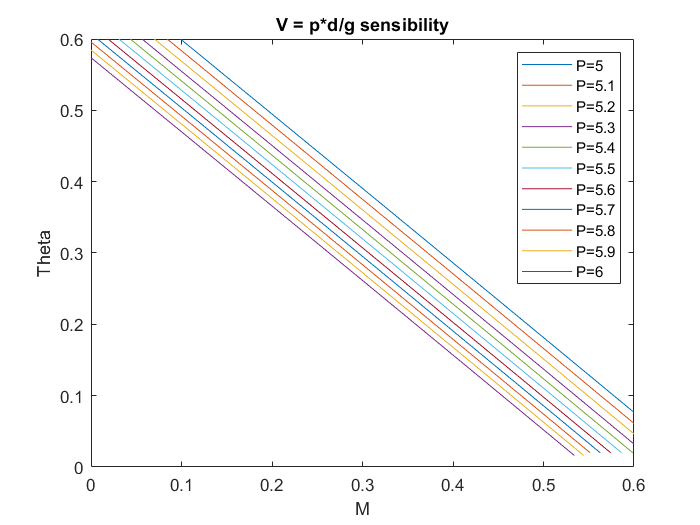

% Initiate
alpha  = 0.1;
beta   = 0.7;
P      = 5:0.1:6;
g      = 0.7;
v      = 10;
Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880];
lgn     = cell(length(P),1);
k       = 1;

% Loop for different p constants
figure()
for i=1:length(P)
    p = P(i);
    warning('off')
    fimplicit(@(M,theta) v_eqn_GammaLevel(M,theta,v,alpha,beta,p));
    hold on
    lgn{k} = strcat('P=',num2str(p));
    k = k+1;
end

xlim([0,0.6])
ylim([0,0.6])
xlabel('M')
ylabel('Theta')
legend(lgn)
title('V = p*d/g sensibility')
saveas(gcf,fullfile(path,'ImagesResults','P_Sensibility.png'))

**Comments**:

Changing the constant p means changing the interception with the theta axis.

Basically, for the same g and v, an increase in this constant will lead to a decrease in mode and increase in theta.

## EQUATION 1 & 2 - Solve for given g and v

% Initiate
alpha   = 0.1;
beta    = 0.7;
p       = 5.5;
g       = 0.70;
v       = 10;

% Set options for solver
x0      = [0.3; 0.2];
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');

% Solve
res    = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[],[],options); % other option
S1          = res(1);
S2          = res(2);
sprintf('mode: %.2f, theta: %.2f',S1,S2)

ans = 'mode: 0.35, theta: 0.27'

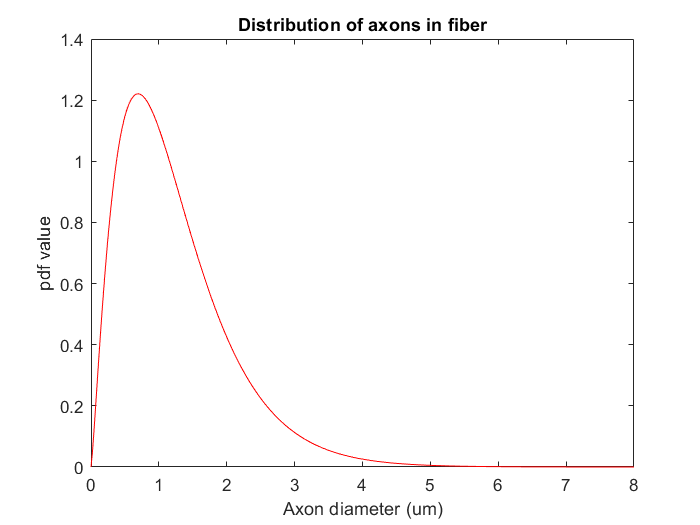

% Display gamma distribution
theta       = S2;
mode        = S1;
shape       = mode/theta+1;
X           = (0:0.01:4);
pdf         = gampdf(X,shape,theta);

figure()
plot(X*2,pdf,'r');
title('Distribution of axons in fiber')
xlabel('Axon diameter (um)')
ylabel('pdf value')

**Comments:**

This is the way to solve the equations. The graphs shown before is just to get an idea how it behaves.

###  EQUATION 1 & 2 - Solve for our data

% Load files
cd(fullfile(path,'Example_images'))
file = dir('g_ratio.nii');
header = spm_vol(file.name);
gratio = spm_read_vols(header);

file = dir('Occipital_mask_tract.nii');
header = spm_vol(file.name);
tract = spm_read_vols(header);

% Initiate
alpha    = 0.1;
beta     = 0.7;
p        = 5.5;
g_map    = gratio.*tract;
v        = 10;
g_number = 1;

for x=1:96
    for y=1:106
        for z=1:70
            if g_map(x,y,z)~= 0 && g_map(x,y,z)> 0.65 && g_number<30 % show only the first 30 solutions
                g=g_map(x,y,z);
                
                % Set options for solver
                x0      = [0.3; 0.2];
                options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
                
                % Solve
                res    = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[],[],options); % other option
                S1          = res(1);
                S2          = res(2);
                sprintf('g-ratio: %.2f, mode: %.2f, theta: %.2f',g,S1,S2)
                g_number = g_number + 1;
                
            end
        end
    end
end

ans = 'g-ratio: 0.66, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.67, mode: 0.57, theta: 0.04'

ans = 'g-ratio: 0.67, mode: 0.58, theta: 0.03'

ans = 'g-ratio: 0.68, mode: 0.48, theta: 0.13'

ans = 'g-ratio: 0.66, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.66, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.01'

ans = 'g-ratio: 0.67, mode: 0.57, theta: 0.03'

ans = 'g-ratio: 0.65, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.66, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.68, mode: 0.51, theta: 0.10'

ans = 'g-ratio: 0.69, mode: 0.43, theta: 0.18'

ans = 'g-ratio: 0.67, mode: 0.57, theta: 0.03'

ans = 'g-ratio: 0.69, mode: 0.42, theta: 0.19'

ans = 'g-ratio: 0.66, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.69, mode: 0.43, theta: 0.19'

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.01'

ans = 'g-ratio: 0.65, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.70, mode: 0.34, theta: 0.28'

ans = 'g-ratio: 0.72, mode: 0.14, theta: 0.49'

ans = 'g-ratio: 0.68, mode: 0.53, theta: 0.08'

ans = 'g-ratio: 0.66, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.68, mode: 0.48, theta: 0.14'

ans = 'g-ratio: 0.68, mode: 0.49, theta: 0.12'

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.01'

ans = 'g-ratio: 0.68, mode: 0.49, theta: 0.12'

ans = 'g-ratio: 0.67, mode: 0.55, theta: 0.06'

ans = 'g-ratio: 0.69, mode: 0.41, theta: 0.21'

**Comments:**

This can take a while, but basically we can see that smaller differences in the g-ratio inside these tract would lead to quite big differences inthe mode and theta values that we find. This has to be solved another way. Sometimes is not even possible to find a solution because the velocity that it's being used is not appropriate to that g-ratio.

## EQUATION 1 & 2 - Sensibility to Alpha and Beta (G and V Space)

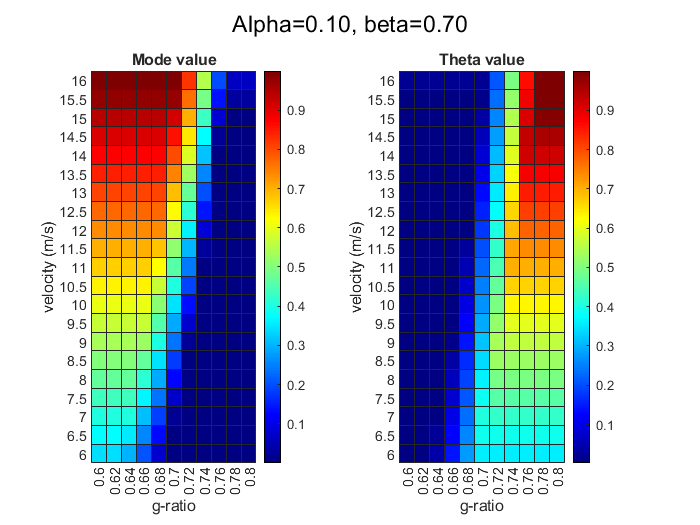

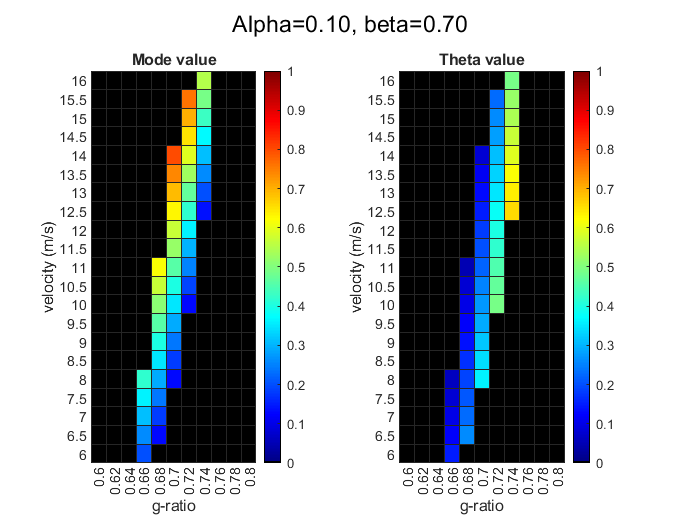

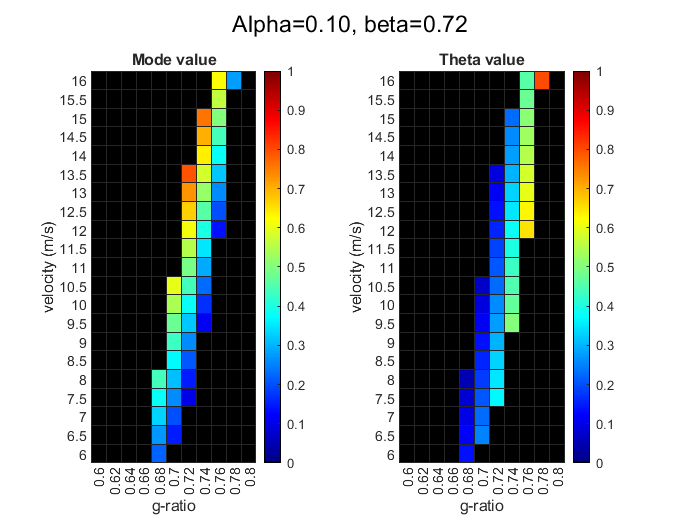

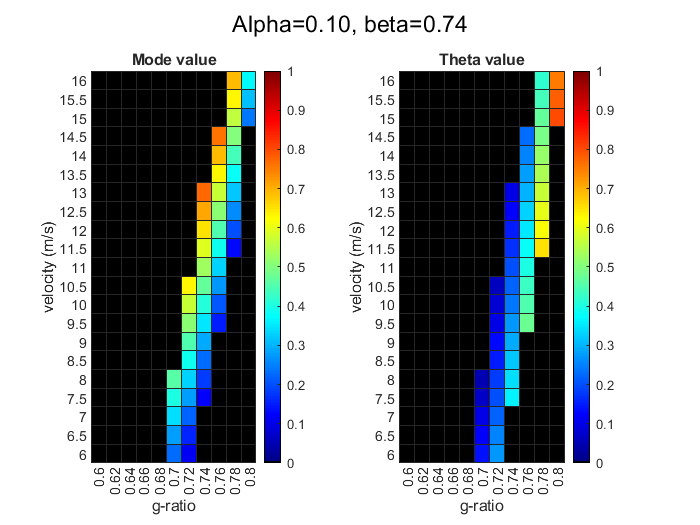

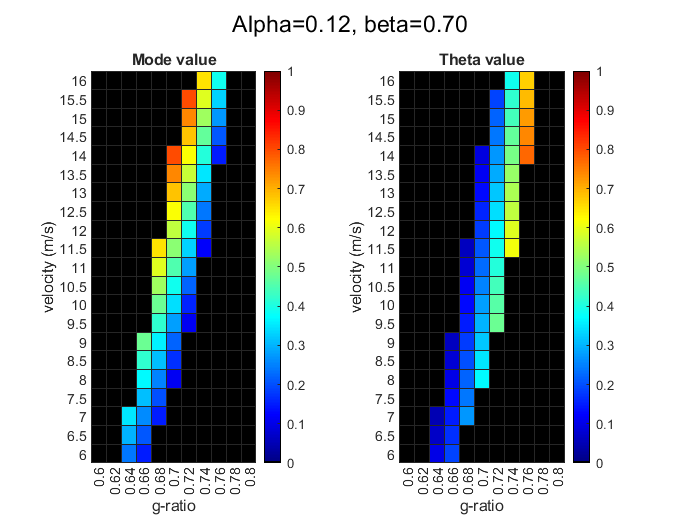

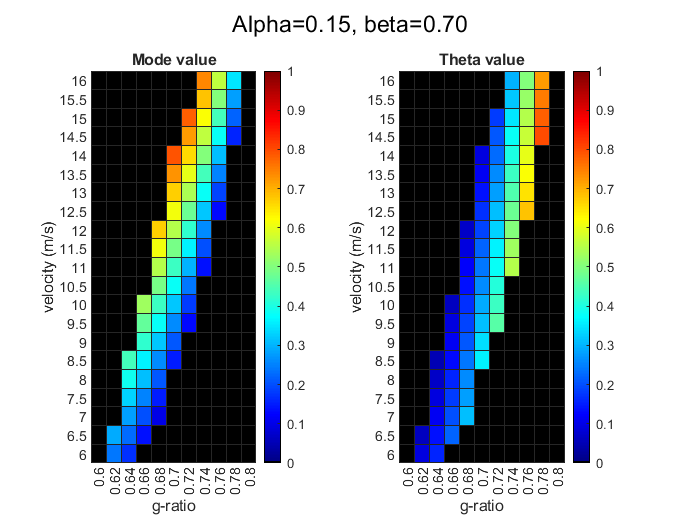

pair_list = [0.1, 0.7; 0.1, 0.72; 0.1, 0.74; 0.12, 0.7; 0.15, 0.7]; % pairs of (alpha,betas) to be tested
p         = 5.5;

for pair=1:length(pair_list)
    % Initiate
    alpha           = pair_list(pair,1);
    beta            = pair_list(pair,2);
    G               = 0.6:0.02:0.8;
    V               = 16:-0.5:6;
    M_matrix        = zeros(length(V),length(G));
    Theta_matrix    = zeros(length(V),length(G));
    
    % Loop through V's
    for i=1:length(V)
        
        v     = V(i);
        M     = [];
        Theta = [];
        
        % Loop through G's
        for j=1:length(G)
            
            g       = G(j);
            
            % Solve equations
            x0      = [0.3;0.1]; % First guess on M and theta
            options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
            
            try
                % if solution is possible add values of Mode and Theta to the
                % matrixes
                res     = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
                M       = [M, res(1)];
                Theta   = [Theta, res(2)];
            catch
                % if solution is not possible (eg, when gamma is not defined) give a value of -3
                % to see as a black square in the plot
                M       = [M, -3];
                Theta   = [Theta, -3];
            end
        end
        
        M_matrix(i,:)       = M;
        Theta_matrix(i,:)   = Theta;
        
    end
    
    % Colormap
    %     greenColorMap   = [zeros(1,192), linspace(1, 0.3, 64)];
    %     ritaColorMap    = [zeros(1, 128), linspace(0.3, 1, 64), zeros(1, 64)];
    %     redColorMap     = [linspace(0, 1, 128), zeros(1, 128)];
    %     colorMap        = [redColorMap; greenColorMap; ritaColorMap]';
    
    % Plot figures
    if pair ==1
        figure(1)
        subplot(1,2,1)
        heatmap(G,V,M_matrix);
        xlabel('g-ratio')
        ylabel('velocity (m/s)')
        title('Mode value')
        subplot(1,2,2)
        heatmap(G,V,Theta_matrix);
        xlabel('g-ratio')
        ylabel('velocity (m/s)')
        title('Theta value')
        colormap(jet);
        sgtitle(sprintf('Alpha=%0.02f, beta=%0.02f',alpha,beta))
    end
    
    % Manipulate matrixes
    M_matrix_new                              = round(M_matrix,2);
    Theta_matrix_new                          = round(Theta_matrix,2);
    M_matrix_new(M_matrix_new<0.1)            = 0; % Remove mode values bellow 0.1 (is not plausible)
    M_matrix_new(M_matrix_new>0.8)            = 0; % Remove mode values above 0.8 (is not plausible)
    Theta_matrix_new(Theta_matrix_new<0.05)   = 0; % Remove theta values bellow 0.05 (is not plausible)
    Theta_matrix_new(Theta_matrix_new>0.8)    = 0; % Remove theta values above 0.8 (is not plausible)
    
    for i=1:size(M_matrix_new,1)
        for j=1:size(M_matrix_new,2)
            if M_matrix_new(i,j)==0
                Theta_matrix_new(i,j)=0;
            end
            if Theta_matrix_new(i,j)==0
                M_matrix_new(i,j)=0;
            end
        end
    end
    
    % Colormap
    colorMap       = jet;
    colorMap(1,:) = [0 0 0];
    
    % Plot figures
    figure()
    subplot(1,2,1)
    heatmap(G,V,M_matrix_new);
    xlabel('g-ratio')
    ylabel('velocity (m/s)')
    title('Mode value')
    caxis([0 1])
    subplot(1,2,2)
    heatmap(G,V,Theta_matrix_new);
    xlabel('g-ratio')
    ylabel('velocity (m/s)')
    title('Theta value')
    caxis([0 1])
    colormap(colorMap);
    sgtitle(sprintf('Alpha=%0.02f, beta=%0.02f',alpha,beta))
    % Save figure
    saveas(gcf,fullfile(path,'ImagesResults',sprintf('Space_Alpha=%0.02f_beta=%0.02f.png',alpha,beta)))
end

**Comments on the general pattern:**

We see a pattern for the mode and the theta. The modes are quite constant in a diagnola line, meaning that if the g-ratio is increased and that increase is accompained by an increase in velocity, the mode will remain constant. This is in agreement with the constant mode assumption.

For the theta the pattern is different: for the same g-ratio the theta doesn't vary much with velocity, meaning that the mode rules this distribution. If if we go to the right (increasing the g-ratio) we see increasing thetas in a vertical way, meaning that if the mode remains more a less constant between g-ratios (above justification), the theta changes a lot between g-ratios, therefore giving a diferent distribution.

**Comments on alpha and beta sensibility:**

Increasing the beta, leads to a shift in the plausible values, meaning that higher g-ratios will be with higher velocities.

Increasing alpha, leads to wider range of plausible values.

## EQUATION 1 & 2 - Solve for given g and v - Plots

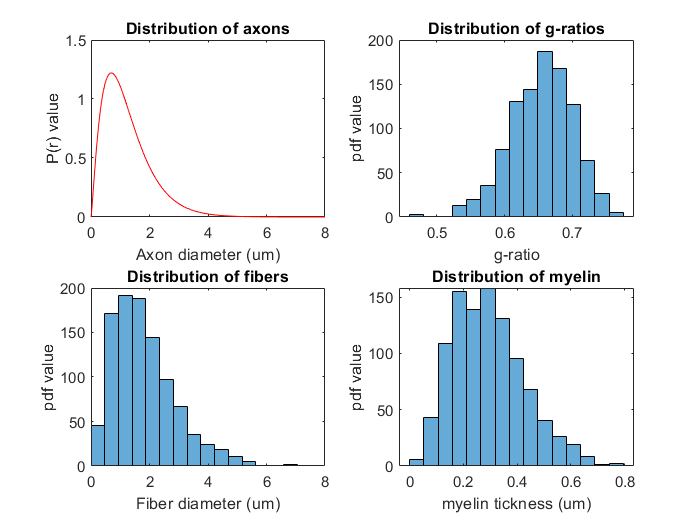

% Initiate
alpha   = 0.1;
beta    = 0.7;
p       = 5.5;
A       = 1.02;
C       = 0.98;
g       = 0.70;
v       = 10;

% Set options for solver
x0      = [0.3; 0.2];
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');

% Solve
res         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[],[],options); % other option
S1          = res(1);
S2          = res(2);

% Display gamma distribution
theta       = S2;
mode        = S1;
shape       = mode/theta+1;
X           = (0:0.01:4);
pdf         = gampdf(X,shape,theta);

figure()
subplot(2,2,1)
plot(X*2,pdf,'r');
title('Distribution of axons')
xlabel('Axon diameter (um)')
ylabel('P(r) value')

% Calculate g-ratio
r  = gamrnd(shape,theta,[1000, 1]);
g  = beta.*r.^alpha;

subplot(2,2,2)
histogram(g,15)
title('Distribution of g-ratios')
xlabel('g-ratio')
ylabel('pdf value')

% Calculate fiber diameter
R = r./g;
D = 2*R;
subplot(2,2,3)
histogram(D,15)
title('Distribution of fibers')
xlabel('Fiber diameter (um)')
ylabel('pdf value')
xlim([0 8])

% Calculate myelin thickness
Mye = R - r;
subplot(2,2,4)
histogram(Mye,15)
title('Distribution of myelin')
xlabel('myelin tickness (um)')
ylabel('pdf value')
saveas(gcf,fullfile(path,'ImagesResults','Distributions.png'))

**Comments:**

For our data we can get values closer to expected. Then we can also compute the fiber diameter and myelin thickness.

## EQUATION 1 & 2 - Sensitivity parameters - one at a time

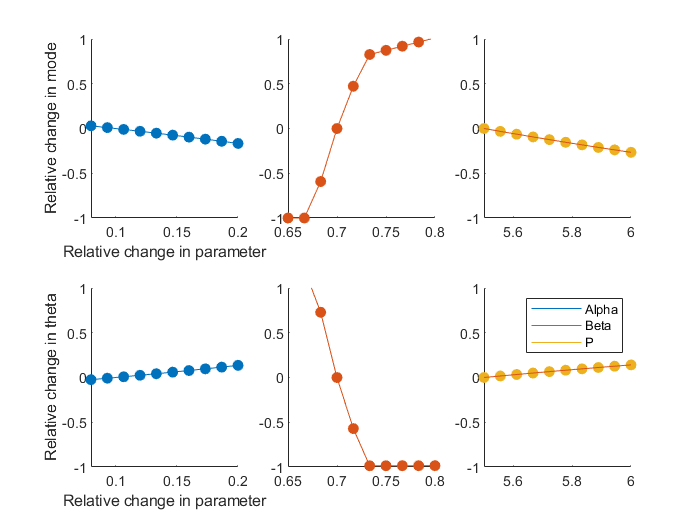

% Initiate
Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880];
%Sample_spc  = -0.04:0.01:0.04;
Sample_spc  = linspace(1,10,10);
figure()

% Set options for solver
x0      = [0.3; 0.2];
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');

% ------------------- Sensibility alpha -------------------
% Initiate
alpha_baseline  = 0.1;
%Alpha           = alpha_baseline+alpha_baseline*Sample_spc;
Alpha           = linspace(0.08,0.2,10);
beta            = 0.7;
p               = 5.5;
g               = 0.70;
v               = 10;
S               = zeros(length(Alpha),2);

% Solve for baseline
res_bas         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha_baseline,beta,p),x0,[],[],options); % other option

for i=1:length(Alpha)
    
    alpha = Alpha(i);
    
    % Solve
    res             = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
    S(i,1)          = res(1)/res_bas(1)-1;
    S(i,2)          = res(2)/res_bas(2)-1;
end

% Plot
subplot(2,3,1)
hold on
scatter(Alpha,S(:,1),'MarkerFaceColor',Color_list(1,:),'MarkerEdgeColor',Color_list(1,:))
hold on
plot(Alpha,S(:,1),'Color',Color_list(1,:))
xlim([min(Alpha), max(Alpha)])
ylim([-1,1])
xlabel('Relative change in parameter')
ylabel('Relative change in mode')
subplot(2,3,4)
hold on
scatter(Alpha,S(:,2),'MarkerFaceColor',Color_list(1,:),'MarkerEdgeColor',Color_list(1,:))
hold on
plot(Alpha,S(:,2),'Color',Color_list(1,:))
xlim([min(Alpha), max(Alpha)])
ylim([-1,1])
xlabel('Relative change in parameter')
ylabel('Relative change in theta')
% --------------------------------------------------------

% ------------------- Sensibility beta -------------------
% Initiate
alpha           = 0.1;
beta_baseline   = 0.7;
%Beta            = beta_baseline+beta_baseline*Sample_spc;
Beta            = linspace(0.65,0.8,10);
p               = 5.5;
g               = 0.70;
v               = 10;
S               = zeros(length(Beta),2);

% Solve for baseline
res_bas         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta_baseline,p),x0,[],[],options); % other option

for i=1:length(Beta)
    
    beta = Beta(i);
    
    % Solve
    res             = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
    S(i,1)          = res(1)/res_bas(1)-1;
    S(i,2)          = res(2)/res_bas(2)-1;
    
end

% Plot
subplot(2,3,2)
hold on
scatter(Beta,S(:,1),'MarkerFaceColor',Color_list(2,:),'MarkerEdgeColor',Color_list(2,:))
hold on
plot(Beta,S(:,1),'Color',Color_list(2,:))
xlim([min(Beta), max(Beta)])
ylim([-1,1])
subplot(2,3,5)
hold on
scatter(Beta,S(:,2),'MarkerFaceColor',Color_list(2,:),'MarkerEdgeColor',Color_list(2,:))
hold on
plot(Beta,S(:,2),'Color',Color_list(2,:))
xlim([min(Beta), max(Beta)])
ylim([-1,1])
% --------------------------------------------------------

% -------------------- Sensibility p ---------------------
% Initiate
alpha           = 0.1;
beta            = 0.7;
p_baseline      = 5.5;
%P               = p_baseline+p_baseline*Sample_spc;
P               = linspace(5.5,6,10);
g               = 0.70;
v               = 10;
S               = zeros(length(P),2);

% Solve for baseline
res_bas         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p_baseline),x0,[0 0],[1 1],options); % other option

for i=1:length(P)
    
    p = P(i);
    
    % Solve
    res             = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[],[],options); % other option
    S(i,1)          = res(1)/res_bas(1)-1;
    S(i,2)          = res(2)/res_bas(2)-1;
end

% Plot
subplot(2,3,3)
hold on
scatter(P,S(:,1),'MarkerFaceColor',Color_list(3,:),'MarkerEdgeColor',Color_list(3,:))
hold on
plot(P,S(:,1),'Color',Color_list(2,:))
xlim([min(P), max(P)])
ylim([-1,1])
subplot(2,3,6)
hold on
scatter(P,S(:,2),'MarkerFaceColor',Color_list(3,:),'MarkerEdgeColor',Color_list(3,:))
hold on
plot(P,S(:,2),'Color',Color_list(2,:))
xlim([min(P), max(P)])
ylim([-1,1])
% --------------------------------------------------------

% Plot stuff just to make legend
hold on
st1 = plot([-2,-1],[-2,-1],'Color',Color_list(1,:));
hold on
st2 = plot([-2,-1],[-2,-1],'Color',Color_list(2,:));
hold on
st3 = plot([-2,-1],[-2,-1],'Color',Color_list(3,:));
legend([st1,st2,st3],{'Alpha','Beta','P'},'Location','northeast')
saveas(gcf,fullfile(path,'ImagesResults','Sensibility_Alpha_Beta_P.png'))

**Comments:**

We can see a linear pattern of change in mode with change in parameter change for the 3 cases.

The response for M and theta is complementary.

Alpha and P influence little the result. As for beta the same does not occur, it really influences the result.

res_bas         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha_baseline,beta_baseline,p_baseline),x0,[0 0],[1 1],options); % other option
p=5.5;
beta=0.8;
alpha=0.1;
g=0.68;
v=8;
                % Solve
for i=1:length(Beta)
                
                beta = Beta(i);
                try
                    % Solve
                    res             = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
                    %if res(1)>0.1 && res(1)<0.8 && res(2)>0.05 && res(2)<0.8
                        S(i,1)          = res(1)-res_bas(1);
                        S(i,2)          = res(2)-res_bas(2);
                    %else
                       % S(i,1)          = 0;
                        %S(i,2)          = 0;
                    %end
                catch
                    S(i,1)          = 0;
                    S(i,2)          = 0;
                end
                
            end                  

## EQUATION 1 & 2 - Sensitivity parameters - one at a time (map)

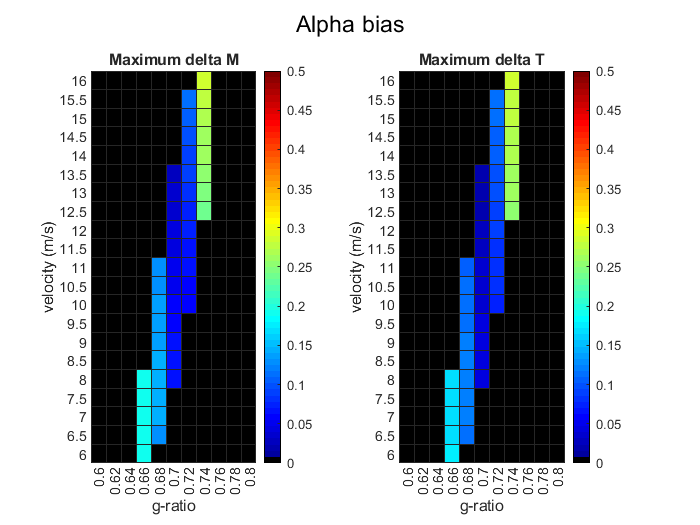

G               = 0.6:0.02:0.8;
V               = 16:-0.5:6;
Alpha_matrix_M    = zeros(length(V),length(G));
Beta_matrix_M     = zeros(length(V),length(G));
P_matrix_M        = zeros(length(V),length(G));
Alpha_matrix_T    = zeros(length(V),length(G));
Beta_matrix_T     = zeros(length(V),length(G));
P_matrix_T        = zeros(length(V),length(G));
alpha_baseline  = 0.1;
beta_baseline   = 0.7;
p_baseline      = 5.5;

% Loop through V's
for vi=1:length(V)
    
    v       = V(vi);
    
    % Loop through G's
    for vj=1:length(G)
        
        g       = G(vj);
        
        % Set options for solver
        x0      = [0.3; 0.2];
        options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
        
        % Solve baseline
        res_bas         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha_baseline,beta_baseline,p_baseline),x0,[0 0],[1 1],options); % other option
        
        if res_bas(1)<0.8 && res_bas(1)>0.1 && res_bas(2)<0.8 &&  res_bas(2)>0.05
            
            % ------------------- Sensibility alpha -------------------
            % Initiate
            Alpha           = linspace(0.08,0.2,10);
            beta            = 0.7;
            p               = 5.5;
            
            for i=1:length(Alpha)
                
                alpha = Alpha(i);
                try
                    % Solve
                    res             = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
                    %if res(1)>0.1 && res(1)<0.8 && res(2)>0.05 && res(2)<0.8
                        S(i,1)          = res(1)-res_bas(1);
                        S(i,2)          = res(2)-res_bas(2);
                    %else
                       % S(i,1)          = 0;
                       % S(i,2)          = 0;
                    %end
                catch
                    S(i,1)          = 0;
                    S(i,2)          = 0;
                end
            end
            
            Alpha_matrix_M(vi,vj) = max(abs(S(:,1)));
            Alpha_matrix_T(vi,vj) = max(abs(S(:,2)));
            % --------------------------------------------------------
            
            % ------------------- Sensibility beta -------------------
            % Initiate
            alpha           = 0.1;
            Beta            = linspace(0.65,0.8,10);
            p               = 5.5;
    
            for i=1:length(Beta)
                
                beta = Beta(i);
                try
                    % Solve
                    res             = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
                    %if res(1)>0.1 && res(1)<0.8 && res(2)>0.05 && res(2)<0.8
                        S(i,1)          = res(1)-res_bas(1);
                        S(i,2)          = res(2)-res_bas(2);
                    %else
                       % S(i,1)          = 0;
                        %S(i,2)          = 0;
                    %end
                catch
                    S(i,1)          = 0;
                    S(i,2)          = 0;
                end
                
            end
            
            Beta_matrix_M(vi,vj) = max(abs(S(:,1)));
            Beta_matrix_T(vi,vj) = max(abs(S(:,2)));
            % --------------------------------------------------------
            
            % -------------------- Sensibility p ---------------------
            % Initiate
            alpha           = 0.1;
            beta            = 0.7;
            P               = linspace(5.5,6,10);
     
            for i=1:length(P)
                
                p = P(i);
                try
                    % Solve
                    res             = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
                    %if res(1)>0.1 && res(1)<0.8 && res(2)>0.05 && res(2)<0.8
                        S(i,1)          = res(1)-res_bas(1);
                        S(i,2)          = res(2)-res_bas(2);
                    %else
                       % S(i,1)          = 0;
                       % S(i,2)          = 0;
                    %end
                catch
                    S(i,1)          = 0;
                    S(i,2)          = 0;
                end
            end
            
            P_matrix_M(vi,vj) = max(abs(S(:,1)));
            P_matrix_T(vi,vj) = max(abs(S(:,2)));
            % --------------------------------------------------------
            
        else 
            Alpha_matrix_M(vi,vj) = 0;
            Alpha_matrix_T(vi,vj) = 0;
            Beta_matrix_M(vi,vj)  = 0;
            Beta_matrix_T(vi,vj)  = 0;
            P_matrix_M(vi,vj)     = 0;
            P_matrix_T(vi,vj)     = 0;
        end
    end
end

colorMap       = jet;
colorMap(1,:) = [0 0 0];
    
% Plot
figure(1)
subplot(1,2,1)
heatmap(G,V,Alpha_matrix_M);
xlabel('g-ratio')
ylabel('velocity (m/s)')
title('Maximum delta M')
caxis([0 0.5])
subplot(1,2,2)
heatmap(G,V,Alpha_matrix_T);
xlabel('g-ratio')
ylabel('velocity (m/s)')
title('Maximum delta T')
caxis([0 0.5])
sgtitle('Alpha bias')
colormap(colorMap);
saveas(gcf,fullfile(path,'ImagesResults','Bias_space_alpha.png'))

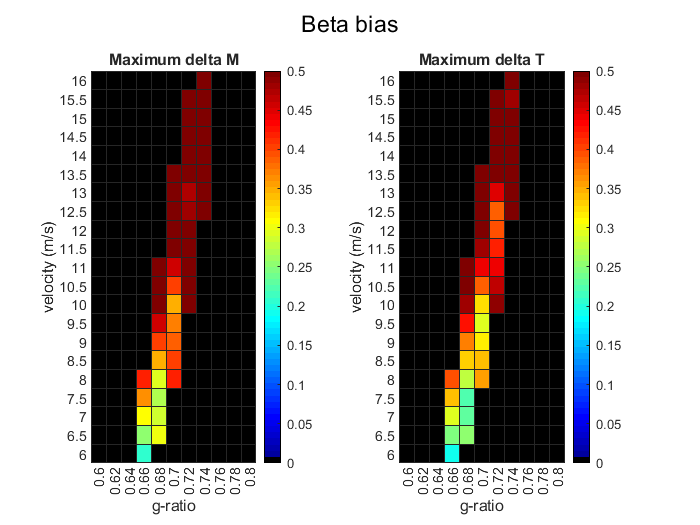

figure(2)
subplot(1,2,1)
heatmap(G,V,Beta_matrix_M);
xlabel('g-ratio')
ylabel('velocity (m/s)')
title('Maximum delta M')
caxis([0 0.5])
subplot(1,2,2)
heatmap(G,V,Beta_matrix_T);
xlabel('g-ratio')
ylabel('velocity (m/s)')
title('Maximum delta T')
caxis([0 0.5])
sgtitle('Beta bias')
colormap(colorMap);
saveas(gcf,fullfile(path,'ImagesResults','Bias_space_beta.png'))

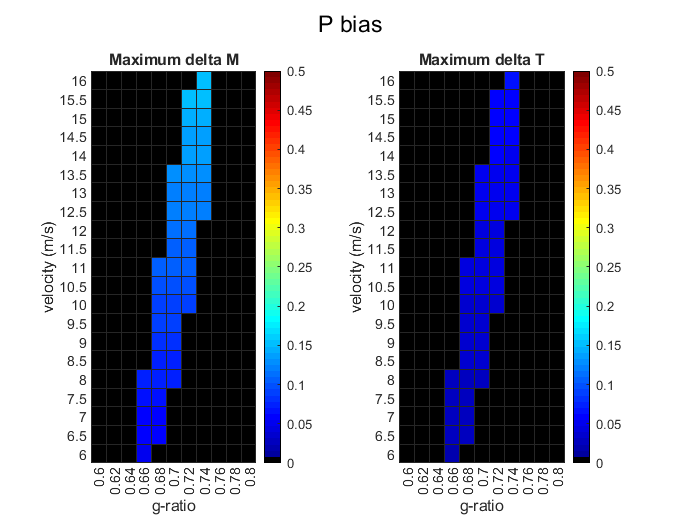

figure(3)
subplot(1,2,1)
heatmap(G,V,P_matrix_M);
xlabel('g-ratio')
ylabel('velocity (m/s)')
title('Maximum delta M')
caxis([0 0.5])
subplot(1,2,2)
heatmap(G,V,P_matrix_T);
xlabel('g-ratio')
ylabel('velocity (m/s)')
title('Maximum delta T')
caxis([0 0.5])
sgtitle('P bias')
colormap(colorMap);
saveas(gcf,fullfile(path,'ImagesResults','Bias_space_P.png'))

**Comments:**

Beta bias seem to be larger than others and there is indeed variability according to the g and v values used.

Increasing alpha means decreasing slighly the mode and essentially increasing the "allowed" solution space. Therefore the errors found are not that big as we had already shown. But they increase if we get away from 0.7, because the main differences between the curves happen for higher or lower g-ratios and around 0.7 are quite similar.

Increasing beta means shifting the solution to the right, so asking that the g-ratios to have higher velocities. Therefore the erros will be huge because compared to the "baseline" the solutions with an increased beta can be quite not realistic (close to zero for mode for example). The fact that beta is not uniform in space might be explained by the same reason as alpha.

An increase in this constant will lead to a decrease in mode and increase in theta, still the range of differences in mode and theta are quite reduced and seems to be more a less consistent between pairs of g and v. So this would influence in a similar way between tracts for example.

If we were to distinguish 2 tracts (occipital and orbitofrontal) we get with the baseline values:

occipital: v=12, mode=0.331, theta=0.427

orbitofrontal: v=8, mode=0.308, theta=0.163

meaning a delta_mode=0.0230 and a delta_theta=0.2640

I guess we have 2 conclusions:

- The bias is not the same in all the same for alpha and beta due to the character of the function where they are used (g=beta*r^(alpha))

- Even if the bias was the spatially constant, and the results would be bias the same way, we would be off to the values that we think are right (alpha=0.1, beta=0.7, p=5.5) for quite a lot and this bias would be bigger than a difference between 2 tracts

## EQUATION 1 & 2 - Sensibility parameters - tudo à molhada

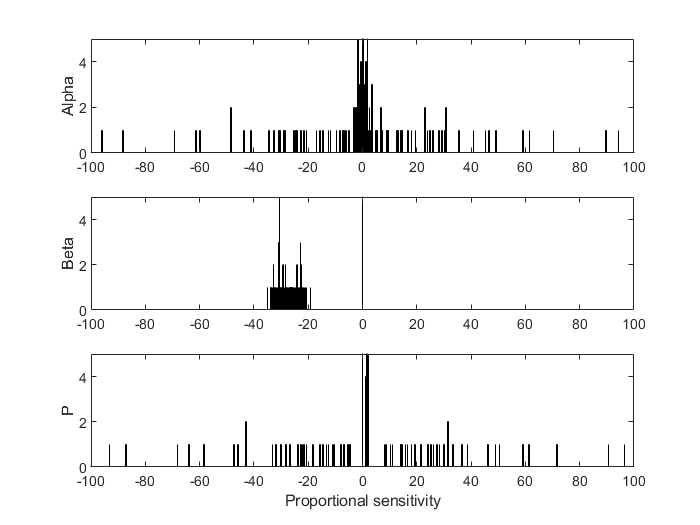

% Set options for solver
x0      = [0.3; 0.2];
options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');

% Initiate
step            = 0.1;
alpha_baseline  = 0.1;
alpha           = alpha_baseline+alpha_baseline*step;
beta_baseline   = 0.7;
beta            = beta_baseline+beta_baseline*step;
p_baseline      = 5.5;
p               = p_baseline+p_baseline*step;

Vector_alpha    = [alpha_baseline,alpha];
Vector_beta     = [beta_baseline,beta];
Vector_p        = [p_baseline,p];
%Vector_com      = combvec(Vector_alpha,Vector_beta,Vector_p);
Alpha           = linspace(0.08,0.2,5);
Beta            = linspace(0.65,0.8,5);
P               = linspace(5.6,6,5);
Sample_spc      = -0.02:0.01:0.02;
Alpha           = alpha_baseline+alpha_baseline*Sample_spc;
Beta            = beta_baseline+beta_baseline*Sample_spc;
P               = p_baseline+p_baseline*Sample_spc;
Sample_spc  = -0.04:0.01:0.04;
Alpha           = alpha_baseline+alpha_baseline*Sample_spc;
Beta            = beta_baseline+beta_baseline*Sample_spc;
P               = p_baseline+p_baseline*Sample_spc;
Vector_com      = combvec(Alpha,Beta,P)';
%Vector_com      = Vector_com(:,2:length(Vector_com))';
logic_vector    = zeros(1,length(Vector_com));
for n=1:length(Vector_com)
    if Vector_com(n,:)==[alpha_baseline,beta_baseline,p_baseline]
        logic_vector(n)=0;
    elseif Vector_com(n,1)==alpha_baseline || Vector_com(n,2)==beta_baseline || Vector_com(n,3)==p_baseline
        logic_vector(n)=1;
    else
        logic_vector(n)=0;
    end
end

Vector_com = Vector_com(logic_vector==1,:);

g               = 0.70;
v               = 10;
S_alpha         = zeros(length(Vector_com),2);
S_beta          = zeros(length(Vector_com),2);
S_p             = zeros(length(Vector_com),2);
ST_alpha        = zeros(1,2);
ST_beta         = zeros(1,2);
ST_p            = zeros(1,2);

Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880];
step        = 0.1;

% Solve for baseline
res_bas         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha_baseline,beta_baseline,p_baseline),x0,[],[],options); % other option

for i=1:length(Vector_com)
    
    % Get variable
    alpha   = Vector_com(i,1);
    beta    = Vector_com(i,2);
    p       = Vector_com(i,3);
    
    try
        % Solve
        res         = lsqnonlin(@(x) make_equations_gv(x,g,v,alpha,beta,p),x0,[0 0],[1 1],options); % other option
        
        % Sensitivity
        S_alpha(i,1)          = (res(1)/res_bas(1)-1)/(alpha/alpha_baseline-1);
        S_alpha(i,2)          = (res(2)/res_bas(2)-1)/(alpha/alpha_baseline-1);
        S_beta(i,1)           = (res(1)/res_bas(1)-1)/(beta/beta_baseline-1);
        S_beta(i,2)           = (res(2)/res_bas(2)-1)/(beta/beta_baseline-1);
        S_p(i,1)              = (res(1)/res_bas(1)-1)/(p/p_baseline-1);
        S_p(i,2)              = (res(2)/res_bas(2)-1)/(p/p_baseline-1);
    catch
        %         % Sensitivity
        %         S_alpha(i,1)          = 0;
        %         S_alpha(i,2)          = 0;
        %         S_beta(i,1)           = 0;
        %         S_beta(i,2)           = 0;
        %         S_p(i,1)              = 0;
        %         S_p(i,2)              = 0;
    end
end

% Removing the infinites (infinites are when the parameter is fixed to the
% baseline)
S_alpha(S_alpha==-Inf)=0;
S_alpha(S_alpha==+Inf)=0;
S_beta(S_beta==-Inf)=0;
S_beta(S_beta==+Inf)=0;
S_p(S_p==-Inf)=0;
S_p(S_p==+Inf)=0;

% Normalize value across parameters
ST_alpha(1,1)          = sum(S_alpha(:,1).^2)/sum(S_alpha(:,1).^2+S_beta(:,1).^2+S_p(:,1).^2)*100;
ST_beta(1,1)           = sum(S_beta(:,1).^2)/sum(S_alpha(:,1).^2+S_beta(:,1).^2+S_p(:,1).^2)*100;
ST_p(1,1)              = sum(S_p(:,1).^2)/sum(S_alpha(:,1).^2+S_beta(:,1).^2+S_p(:,1).^2)*100;

% Plot Sensitivity
figure()
subplot(3,1,1)
histogram(S_alpha(:,1),1000)
ylabel('Alpha','Rotation',90)
xlim([-100,100])
ylim([0,5])
subplot(3,1,2)
histogram(S_beta(:,1),1000)
ylabel('Beta','Rotation',90)
xlim([-100,100])
ylim([0,5])
subplot(3,1,3)
histogram(S_p(:,1),1000)
ylabel('P','Rotation',90)
xlim([-100,100])
ylim([0,5])
xlabel('Proportional sensitivity')

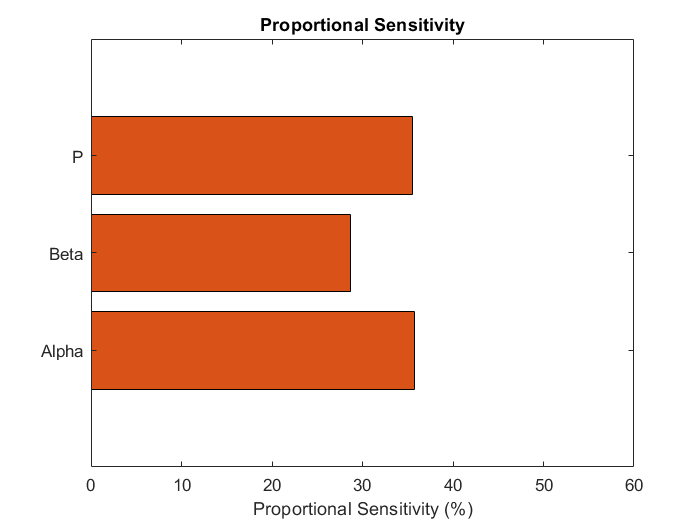

% Plot normalized sensitivity
figure()
barh([ST_alpha(1),ST_beta(1),ST_p(1)],'FaceColor',[0.85, 0.325, 0.098])
yticklabels({'Alpha','Beta','P'})
xlabel('Proportional Sensitivity (%)')
title('Proportional Sensitivity')
xlim([0 60])
saveas(gcf,fullfile(path,'ImagesResults','Sensibility_Alpha_Beta_P_2.png'))

**Comments:**

Confirmar se isto está bem! Parece-me que faz sentido mas mt confusa :s

Basicamente temos 3 variáveis e iremos comparar 2 valores de cada uma (baseline e outro valor) e o objetivo é ir fixando os valores de umas e de outras manter livre.

Isso dá 2^3 -1 comparações (o -1 é porque uma delas é fixando os parametros todos e não faz sentido). Deste número de comparaçoes (7), 3 delas são fixando o valor que estamos a medir, pelo que não vai fazer sensibilidade nenhuma, ou seja, assim, para cada parametro, teremos apenas 4 valores de sensibilidade (4 valores para os quais este parametro varia). No paper do Draksmith ele diz mesmo que o número de comparações será 2^(3-1)=4, por isso acho que faz sentido.

Depois arranjamos as sensibilidades e podemos dividi-las pelas sensibilidades totais para dar uma % relativa ao todo. 

Vimos que o parametro beta é o que influencia mais os resultados (cerca de 50%), já poderiamos ver isto um pouco nos resultados da secção anterior, a única diferença é que antes estavamos a considerar alterações de parâmetros individualmente e aqui estamos a deixar que eles alterem em conjunto.

# Definition of functions in Matlab - For Numeric Solver

### Equation 1 (g-ratio):

function F = g_eqn_EasyLevel(M,theta,g,alpha,beta,A) % EASY LEVEL
F = [-g^2 + (beta^2*theta^(2*alpha) ...
    * A*(M/theta)^(2*alpha) ... % Lower limit and factor A
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M))];
end

function F = g_eqn_HardLevel(M,theta,g,alpha,beta) % HARD LEVEL
F = [-g^2 + beta^2*theta^(2*alpha) ...
    * (M/theta+1/2-alpha)^(2*alpha) ... % Complex limit without factor
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M)];
end

function F = g_eqn_GammaLevel(M,theta,g,alpha,beta) % GAMMA LEVEL
F = [-g^2 + beta^2*theta^(2*alpha) ...
    * gamma(M/theta+1)/gamma(M/theta+1-2*alpha) ... % Without approximmation
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M)];
end


### Equation 2 (velocity):

function F = v_eqn_EasyLevel(M,theta,v,alpha,beta,C) % EASY LEVEL
F = [-v + ((2*5.5)/beta)*theta^(1-alpha) ...
    * C*(M/theta)^(-alpha) ... % Lower limit and factor A
    * (M/theta+1-alpha)];
end

function F = v_eqn_HardLevel(M,theta,v,alpha,beta) % HARD LEVEL
F = [-v + ((2*5.5)/beta)*theta^(1-alpha) ...
    * (M/theta+1/2-alpha/2)^(-alpha) ... % Complex limit without factor
    * (M/theta+1-alpha)];
end

function F = v_eqn_GammaLevel(M,theta,v,alpha,beta,p) % GAMMA LEVEL
F = [-v + ((2*p)/beta)*theta^(1-alpha) ...
    * gamma(M/theta+1-alpha)/gamma(M/theta+1) ... % Without approximmation
    * (M/theta+1-alpha)];
end

### Equation 1 and 2 (g-ratio and velocity):

function F = make_equations_gv(x,g,v,alpha,beta,p)

% Variables
M = x(1);
theta = x(2);

F = [   % g-ratio equation:
    -g^2 + beta^2*theta^(2*alpha) ...
    * gamma(M/theta+1)/gamma(M/theta+1-2*alpha) ... % Without approximmation
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M);
    
    % velocity equation:
    -v + ((2*p)/beta)*theta^(1-alpha) ...
    * gamma(M/theta+1-alpha)/gamma(M/theta+1) ... % Without approximmation
    * (M/theta+1-alpha)];
end

# Definition of functions in Matlab - For Symbolic Solver

### Equation 1 (g-ratio):

function [g_sym_eqn_EasyLevel, g_sym_eqn_HardLevel,g_sym_eqn_GammaLevel] = make_sym_equations_g(M,theta,g,alpha,beta,A)
g_sym_eqn_EasyLevel     = g^2 == beta^2*theta^(2*alpha) ...
    * A*(M/theta)^(2*alpha) ... % Lower limit and factor A
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M);
g_sym_eqn_HardLevel         = g^2 == beta^2*theta^(2*alpha) ...
    * (M/theta+1/2-alpha)^(2*alpha) ... % Complex limit without factor
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M);
g_sym_eqn_GammaLevel        = g^2 == beta^2*theta^(2*alpha) ...
    * gamma(M/theta+1)/gamma(M/theta+1-2*alpha) ... % Without approximmation
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M);
end

### Equation 2 (velocity):

function [v_sym_eqn_EasyLevel, v_sym_eqn_HardLevel,v_sym_eqn_GammaLevel] = make_sym_equations_v(M,theta,v,alpha,beta,C)
v_sym_eqn_EasyLevel     = v == ((2*5.5)/beta)*theta^(1-alpha) ...
    * C*(M/theta)^(-alpha) ... % Lower limit and factor A
    * (M/theta+1-alpha);
v_sym_eqn_HardLevel         = v == ((2*5.5)/beta)*theta^(1-alpha) ...
    * (M/theta+1/2-alpha/2)^(-alpha) ... % Complex limit without factor
    * (M/theta+1-alpha);
v_sym_eqn_GammaLevel        = v == ((2*5.5)/beta)*theta^(1-alpha) ...
    * gamma(M/theta+1-alpha)/gamma(M/theta+1) ... % Without approximmation
    * (M/theta+1-alpha);
end